clf reset
clc
%load 4V data
lab_data_4v = readtable("comb_part1_4v.csv");
simu_v4k100 = readtable("100k4v_simu.csv");
simu_v4k20 = readtable("20k4v_simu.csv");

real_t_1_4v = table2array(lab_data_4v(:,"t_in_100"));
real_t_2_4v = table2array(lab_data_4v(:,"t_out_100"));
real_v_in_100k_4v = table2array(lab_data_4v(:,"v_in_100"));
real_v_out_100k_4v = table2array(lab_data_4v(:,"v_out_100"));
real_v_in_20k_4v = table2array(lab_data_4v(:,"v_in_20"));
real_v_out_20k_4v = table2array(lab_data_4v(:,"v_out_20"));

simu_v_in_100k_4v = table2array(simu_v4k100(:,"vin_simu_100k_4v"));
simu_v_out_100k_4v = table2array(simu_v4k100(:,"vout_simu_100k_4v"));
simu_v_in_20k_4v = table2array(simu_v4k20(:,"vin_20k_4v"));
simu_v_out_20k_4v = table2array(simu_v4k20(:,"vout_20k_4v"));

%load 5v data
lab_data_5v = readtable("comb_part1.csv");
simu_v5k100 = readtable("100k5v_simu.csv");
simu_v5k20 = readtable("20k5v_simu.csv");

real_t_1 = table2array(lab_data_5v(:,"t_1"));
real_t_2 = table2array(lab_data_5v(:,"t_2"));
real_v_in_100k_5v = table2array(lab_data_5v(:,"v_1"));
real_v_out_100k_5v = table2array(lab_data_5v(:,"v_2"));
real_v_in_20k_5v = table2array(lab_data_5v(:,"v_1_20"));
real_v_out_20k_5v = table2array(lab_data_5v(:,"v_2_20"));

simu_v_in_100k_5v = table2array(simu_v5k100(:,"vin"));
simu_v_out_100k_5v = table2array(simu_v5k100(:,"vout"));
simu_v_in_20k_5v = table2array(simu_v5k20(:,"vin_20k"));
simu_v_out_20k_5v = table2array(simu_v5k20(:,"vout_20k"));

100k real vs simu 4v vs 5v

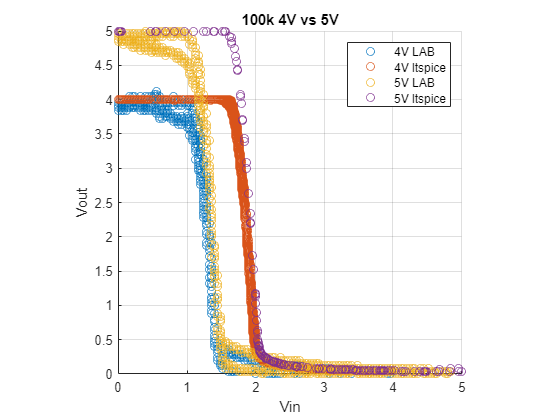

hold on
scatter(real_v_in_100k_4v, real_v_out_100k_4v)
scatter(simu_v_in_100k_4v, simu_v_out_100k_4v)
scatter(real_v_in_100k_5v, real_v_out_100k_5v)
scatter(simu_v_in_100k_5v, simu_v_out_100k_5v)
title("100k 4V vs 5V")
grid on
axis square
xlim([0 5])
ylim([0 5])
xlabel("Vin")
ylabel("Vout")
legend("4V LAB", "4V ltspice", "5V LAB", "5V ltspice")
hold off

20K real vs simu

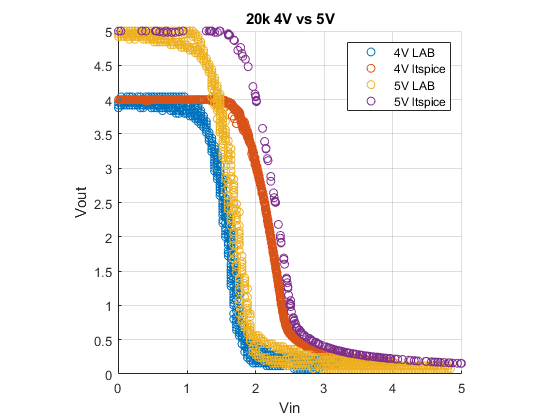

figure
hold on
scatter(real_v_in_20k_4v, real_v_out_20k_4v)
scatter(simu_v_in_20k_4v, simu_v_out_20k_4v)
scatter(real_v_in_20k_5v, real_v_out_20k_5v)
scatter(simu_v_in_20k_5v, simu_v_out_20k_5v)
title("20k 4V vs 5V")
grid on
axis square
xlim([0 5])
ylim([0 5])
xlabel("Vin")
ylabel("Vout")
legend("4V LAB", "4V ltspice", "5V LAB", "5V ltspice")
hold off

100k real vs real

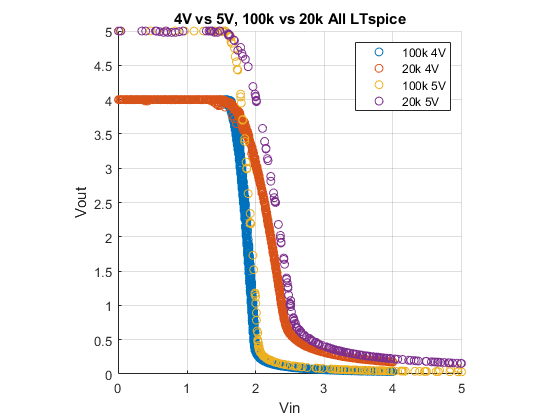

figure
hold on
scatter(simu_v_in_100k_4v, simu_v_out_100k_4v)
scatter(simu_v_in_20k_4v, simu_v_out_20k_4v)
scatter(simu_v_in_100k_5v, simu_v_out_100k_5v)
scatter(simu_v_in_20k_5v, simu_v_out_20k_5v)
title("4V vs 5V, 100k vs 20k All LTspice")
grid on
axis square
xlim([0 5])
ylim([0 5])
xlabel("Vin")
ylabel("Vout")
legend("100k 4V", "20k 4V", "100k 5V", "20k 5V")
hold off

100k simu vs simu

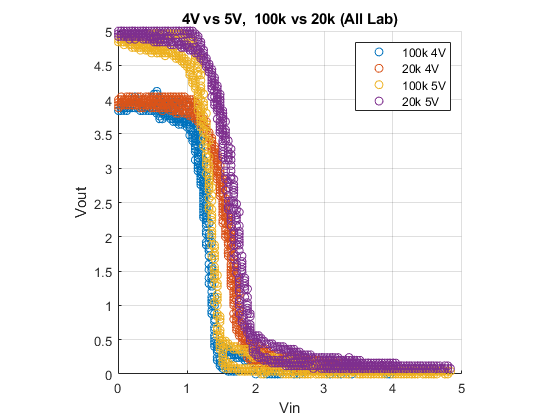

figure
hold on
scatter(real_v_in_100k_4v, real_v_out_100k_4v)
scatter(real_v_in_20k_4v, real_v_out_20k_4v)
scatter(real_v_in_100k_5v, real_v_out_100k_5v)
scatter(real_v_in_20k_5v, real_v_out_20k_5v)
title("4V vs 5V,  100k vs 20k (All Lab)")
grid on
axis square
xlim([0 5])
ylim([0 5])
xlabel("Vin")
ylabel("Vout")
legend("100k 4V", "20k 4V", "100k 5V", "20k 5V")
hold off

YT plots

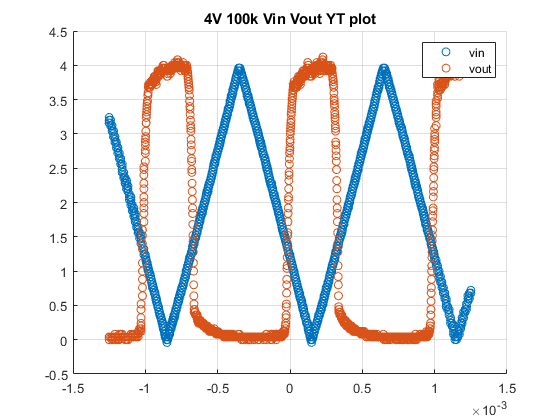

figure
hold on
scatter(real_t_1_4v, real_v_in_100k_4v)
scatter(real_t_2_4v, real_v_out_100k_4v)
title("4V 100k Vin Vout YT plot")
grid on
legend("vin", "vout")
hold off

Find critical points

function [v_oh, v_ol, v_ih, v_il v_th] = find_crit_points(input_voltage, output_voltage)
    vtc = output_voltage / input_voltage;
end